# Using simulink to visualise hydraulic system behaviour

The control101 toolbox focuses mainly on linear models and thus simple MATLAB code is sufficient to illustrate the core behaviours. However, the real world is full of more complex components and connections. In such cases writing code can be messy or difficult and it is often easier to capture the scenario using tools such as simulink.

This livescript is a brief introduction to the use of simulink to model and simulate a simple hydraulic systems. More importantly, it shows how integration with MATLAB code can make running the simulink file very efficient to allow systematic investigations for a range of parameter values. This livescript file makes use of the following simulink file:

- Hydraulic_system_control101.slx 

For more generic and comprehensive help on and introduction to Simulink, use the Mathworks onramp website.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help control101  % this line only works if the toolbox is installed

File written by J.A.Rossiter, University of Sheffield                         

## Preamble

Many simulink files have a large number of parameters which are most conveniently defined with a supporting MATLAB script and thus one might as well run the simulink file directly from the same script. This resource uses the simple options of a step input and a scope for import and export and thus is the simplest example of using simulink to investigate system behaviours.

For more generic and comprehensive help on and introduction to Simulink, use the Mathworks onramp website.

## 1. Simple hydraulic system models

A tank system is taken to have a controllable flow into the tank, for example from the top, and an outflow that depends upon the depth (linear assumption). We consider 3 different tank set ups.

The input flow depends upon an input signal u through a gain, that is:


$$q_i =k_p u$$


### 1.1 A single tank

A schematic is given in Figure 1.1. For this a simple model is given as:

$A\frac{\mathrm{dh}}{\mathrm{dt}}=q_i -q_o ;\;\;\;\;\;\;\;\;q_o =\frac{1}{R}\left(p-p_o \right);\;\;\;\;\;\;\;\;\;\;\;\left(p-p_o \right)=\rho \mathrm{gh}$;        $\mathrm{Ca}=\frac{\rho g}{R}$

where *p* is the pressure at the bottom of the tank and $p_o$ the atmospheric pressure. *h* is the depth and *R* a constant that depends on the outflow pipe parameters *C,a*. In transfer function format one can write:


$$H\left(s\right)=\frac{1}{\mathrm{As}+\frac{\rho g}{R}}q_i \left(s\right)=G\left(s\right)q_i \left(s\right);\;\;\;\;\;\;\;\;G\left(s\right)=\frac{1}{A\;\;s+C\;a}$$


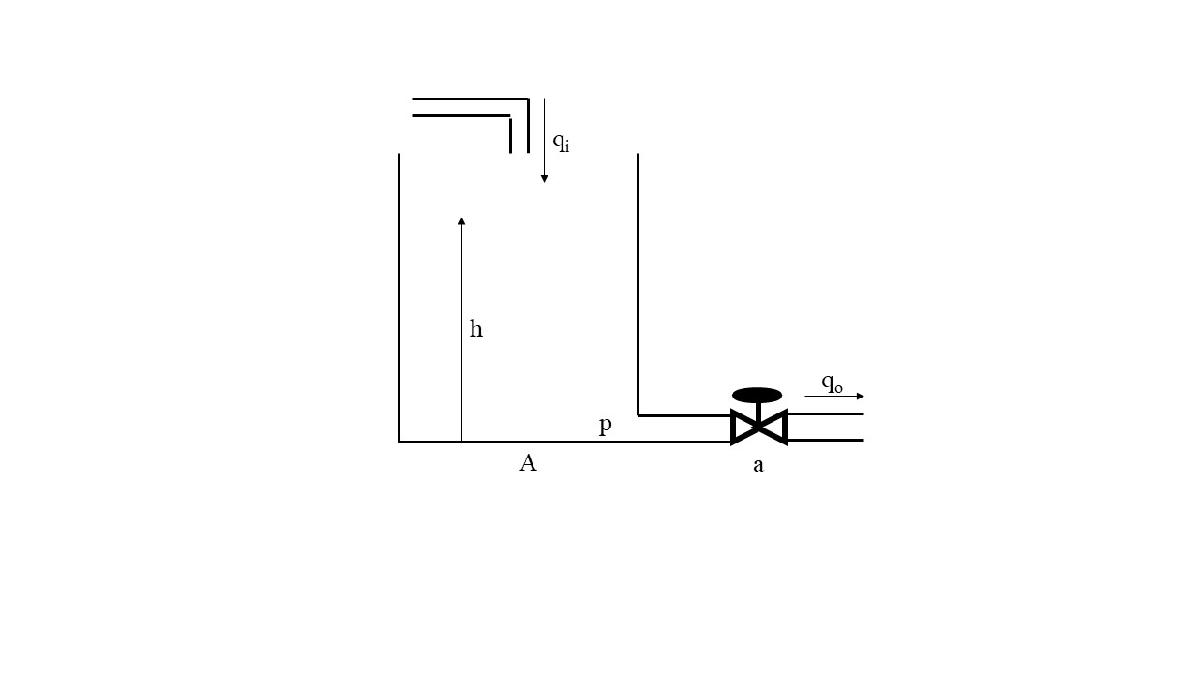

**Figure 1.1 **A single tank

### 1.2 Two tanks in series

Modelling this is quite similar to a single tank in that we simply combine two single tank models.


$$H_1 \left(s\right)=\frac{1}{A_1 s+C_1 a_1 }q_i \left(s\right)=G_1 \left(s\right)q_i \left(s\right);\;\;\;\;\;\;\;\;\;\;\;\to \;\;q_1 \left(s\right)=C_1 a_1 H_1 \left(s\right)$$



$$H_2 \left(s\right)=\frac{1}{A_2 s+C_2 a_2 }q_1 \left(s\right)=\frac{C_1 a_1 }{A_2 s+C_2 a_2 }H_1 \left(s\right)=G_2 \left(s\right)H_1 \left(s\right)\;\;\to \;\;H_2 \left(s\right)=G_2 \left(s\right)G_1 \left(s\right)q_i \left(s\right)\;\;$$


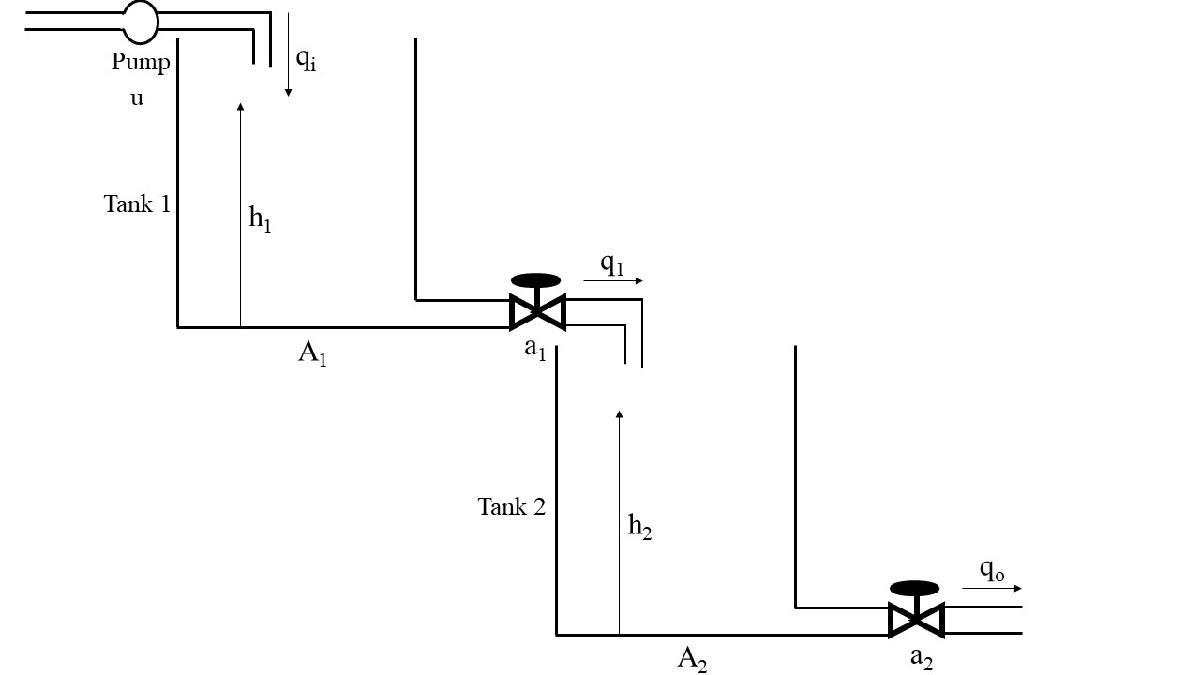

**Figure 1.2 **Two tanks in series

This system of equations can be represented in simulink using the following block diagrams. Open the simulink file to investigate more carefully and/or to make changes. From within simulink, double click on any block to see how the parameters have been defined within that block.

**Figure 1.3**: Screen capture of*** Hydraulic_System_control101.slx.*** We have deliberate left in the 'red' around the boxes as this is a warning that the required parameters have not yet been defined in the workspace. Once the parameters are defined, the red will disappear.

### 1.3 Two tanks in parallel

Parallel arrangements are more complicated because the flow between the tanks depends upon the relative depths and this provides a feedback term between the tanks. Hence:


$$A_1 \frac{dh_1 }{\mathrm{dt}}=q_i -q_1 ;\;\;\;\;\;\;\;\;q_1 =C_1 a_1 \left(h_1 -h_2 \right);\;\;\;\;\;\;\to \;\;\;\;H_1 \left(s\right)=\left\lbrack \frac{1}{A_1 s+C_1 a_1 }\right\rbrack q_i \left(s\right)-\left\lbrack \frac{C_1 a_1 }{A_1 s+C_1 a_1 }\right\rbrack H_2 \left(s\right)$$



$$A_2 \frac{dh_2 }{\mathrm{dt}}=q_1 -q_o ;\;\;\;\;\;\;\;\;q_o =C_2 a_2 \left(h_2 \right)\;\;\;\;\;\to \;\;\;\;\;\;\;H_2 \left(s\right)=\left\lbrack \frac{C_1 a_1 }{A_2 s+C_2 a_2 +C_1 a_1 }\right\rbrack H_1 \left(s\right)$$


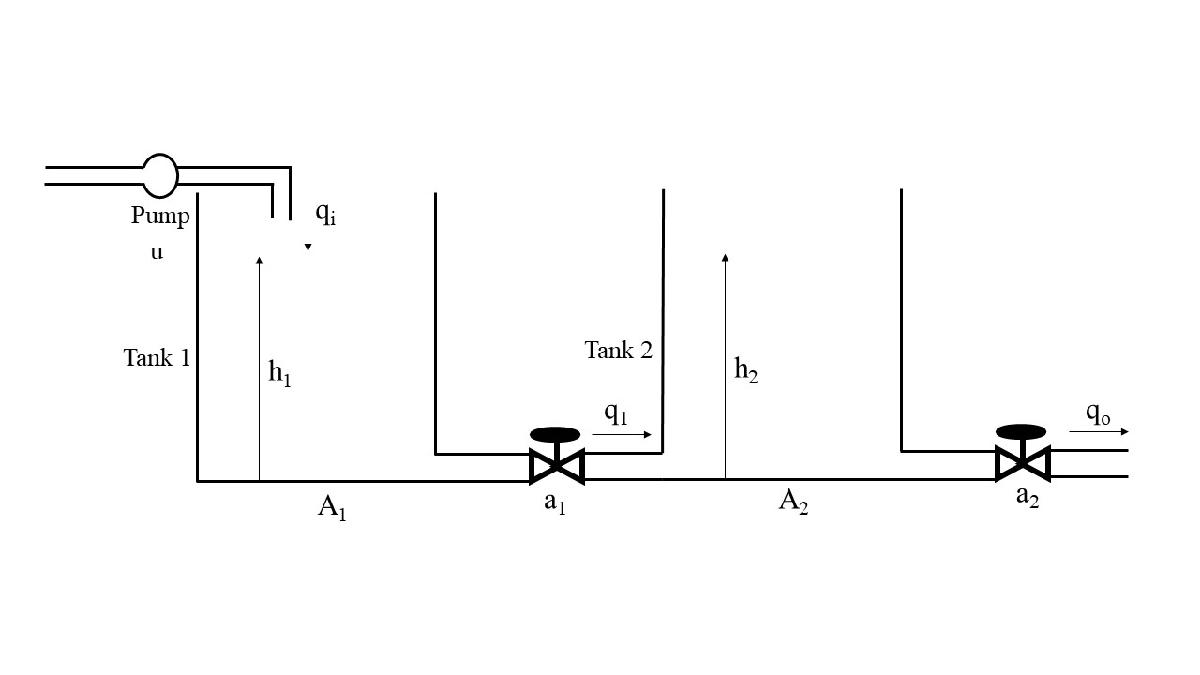

**Figure 1.4 **Two tanks in parallel

This system of equations can be represented in simulink using the following block diagram. Open the simulink file to investigate more carefully and/or to make changes. From within simulink, double click on any block to see how the parameters have been defined within that block and notice how they match the definitions in this section.

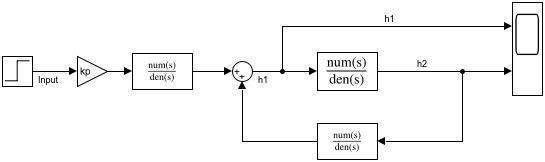

**Figure 1.5**: Screen capture of*** Hydraulic_Systemb_control101.slx.*** Notice that here the parameters have been defined so there is no red.

## 2. Simulation of the tank system models

We need to define all the required parameters before running the simulink file. This includes:

- Component values.

- Initial conditions are taken as zero for simplicity.

The values can be defined through a MATLAB script (see code below), after which we can run the simulink model and determine the behaviours. In this case, the depths are plotted only in a scope so you need to open the scope to see the results.

### 2.1 Simulation for tanks in series

disp('*****************************')

*****************************


disp('Section 2.1 illustrations below')

Section 2.1 illustrations below



% to open simulink file and view the scope
open Hydraulic_System_control101.slx  

% Define parameters needed by simulink file
A1=0.01;
A2=0.01;
a1=0.4E-4;
a2=0.32E-4;
C1=12;
C2=12;
kp=15E-6;

% Simulation - results will appear in the scope
sim("Hydraulic_System_control101.slx");


%print(['-sHydraulic_System_control101'],'-djpeg',['Hydraulic_System_control101.jpg'])

### 2.2 Simulation for tanks in parallel

The code here simply changes the choice of simulink file. You can see how behaviour is very different for different arrangements of tanks.

disp('*****************************')
disp('Section 2.2 illustrations below')

*****************************


Section 2.2 illustrations below


% to open simulink file and view the scope
open Hydraulic_Systemb_control101.slx  

A1=0.01;
A2=0.01;
a1=0.2E-4;
a2=0.32E-4;
C1=12;
C2=12;
kp=15E-6;

% Simulation - results will appear in the scope
sim("Hydraulic_Systemb_control101.slx");

%print(['-sHydraulic_Systemb_control101'],'-djpeg',['Hydraulic_Systemb_control101.jpg'])